clear
filename="\\NIFS\experiment\results\Doppler\Photron\211224\Ar_dial4727_shot28_450000fps_1.5us_gain44\Ar_dial4727_shot28_450000fps_1.5us_gain44"

filename = "\\NIFS\experiment\results\Doppler\Photron\211224\Ar_dial4727_shot28_450000fps_1.5us_gain44\Ar_dial4727_shot28_450000fps_1.5us_gain44"

[fps,nframe]= importfile(filename+".cih")

fps = 450000

nframe = 401

frame_time=(1000000.)/fps

frame_time = 2.2222

line=str2double(extractBetween(filename,'_','dial'))*0.1;
mass=40 %%後でfilenameにArが含まれているかでmassを設定する

mass = 40

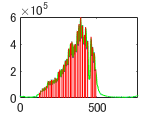

liner_dispersion=0.014;
sp=120;
ep=sp+400;
data=imread(filename+".tif",1);
for i=1:nframe
    data=data+imread(filename+".tif",i);
    data2(:,:,i)=imread(filename+".tif",i);
end
channel_0D=sum(data,1);
[extremum,~]=islocalmax(smooth(channel_0D,'lowess'),'MinSeparation',8);

plot(channel_0D);
hold on
plot(smooth(channel_0D,'lowess'),'-g')
for i=1:numel(channel_0D)
    if extremum(i) && i>sp && i<ep
        plot([i, i],[0, channel_0D(i)],'-r')
    end
end
hold off

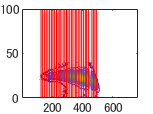


contour(data,15)
hold on
xx=0;
px=1:numel(channel_0D);
for i=px
    if extremum(i) && i>=sp && i<=ep
        xx=xx+1;
        plot([i, i],[0, 100],'-r')
        spectrum_1D(:,xx,:)=sum(data2(:,i-4:i+4,:),2);
    end
end
extremum=px(extremum);
extremum(extremum<sp)=[];
extremum(extremum>ep)=[];
hold off

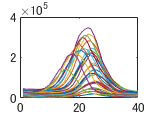

time=[1:nframe]*frame_time;
time_evo_temp=zeros(nframe,xx);
channel_spectrum=sum(spectrum_1D,3);
plot(squeeze(channel_spectrum))

channel_center=[1:xx];
gaussEqn = 'a*exp(-((x-b)/c)^2)+d'

gaussEqn = 'a*exp(-((x-b)/c)^2)+d'

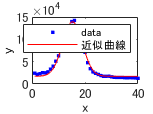

for i=1:xx
    fitting=fit([1:numel(data(:,i))]',channel_spectrum(:,i),gaussEqn,'Start',[150000,15,5,20000]);
    plot(fitting,[1:numel(data(:,i))]',channel_spectrum(:,i))
    a=coeffvalues(fitting);
    channel_center(i)=a(2);
end

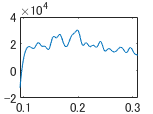


%%ここから発光強度abel-inversion
num=300;
n_chord=xx;
r_max=0.309 ;
r_min=0.092 ;
emission_int=flip(squeeze(sum(spectrum_1D,1)));
%emission_int=squeeze(sum(spectrum_1D,1));
r_laser=(1:n_chord)/(n_chord-1)*(r_max-r_min)+r_min;%レーザー座標
y_interp=(1:num)/(num-1)*(r_max-r_min)+r_min;%interp位置
emission_interp=zeros(numel(y_interp),nframe);
dy=(r_max-r_min)/num;
dndy=zeros(num,nframe);
reconst_int=zeros(num,nframe);
for i=1:nframe
emission_interp(:,i)=spline(r_laser,emission_int(:,i),y_interp);
dndy(:,i)=gradient(emission_interp(:,i),y_interp);
end

for i=1:nframe
 for j=1:num-1 
  for k=j+1:num-1 
    reconst_int(j,i)=reconst_int(j,i)-1./pi.*dndy(k,i)./sqrt(y_interp(k).^2-y_interp(j).^2).*dy;
  end
 end
end

reconst_int(reconst_int <= 0)=0;
plot(y_interp,emission_interp(:,210))

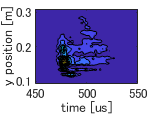

contourf(time,y_interp,reconst_int) %contour,transpose(reconst_int),time,y_interp,/fill,nlevels=256,xr=[450,500],yr=[r_min,r_max],zr=[0,max(reconst_int)*0.5],xtitle="time [us]",ytitle="y position [m]"

xlim([450 550])
ylim([r_min r_max])
xlabel("time [us]")
ylabel("y position [m]")


upper_grid=10

upper_grid = 10

lower_grid=10

lower_grid = 10

ngrid=upper_grid+lower_grid+1

ngrid = 21

calib_grid=zeros(ngrid,xx,nframe)

calib_grid = calib_grid(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  


for i=1:xx 
calib_grid(:,i,:)=sum(data2(fix((channel_center(i))-lower_grid):fix(channel_center(i))+upper_grid,extremum(i)-4:extremum(i)+4,:),2);
end
grid_interp=zeros(num,ngrid,nframe)

grid_interp = grid_interp(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0   

for i=1:ngrid 
 for j=1:nframe 
 grid_interp(:,i,j)=spline(r_laser,calib_grid(:,i,j),y_interp)
 end
end
% window,7
% grid_interp=reverse(grid_interp)
% plot,y_interp,grid_interp[*,10,210]
% dndy_2=fltarr(num,ngrid,nframe)

function [fps,nframe] = importfile(filename)
%IMPORTFILE テキスト ファイルからデータをインポート
%  AR4727DIAL6682SHOT171USGAIN35CROWBAR200000FPS200FRAME =
%  IMPORTFILE(FILENAME) は既定の選択に関してテキスト ファイル FILENAME からデータを読み取ります。
%  数値データを返します。
%
%  AR4727DIAL6682SHOT171USGAIN35CROWBAR200000FPS200FRAME =
%  IMPORTFILE(FILE, DATALINES) はテキスト ファイル FILENAME
%  の指定された行区間のデータを読み取ります。DATALINES
%  を正の整数スカラーとして指定するか、行区間が不連続の場合は正の整数スカラーからなる N 行 2 列の配列として指定します。
%
%  例:
%  Ar4727dial6682shot171usgain35crowbar200000fps200frame = importfile("\\NIFS\experiment\results\Doppler\Photron\211217\Ar_4727dial6682_shot17_1us_gain35_crowbar_200000fps_200frame.cih", [16, 16]);
%
%  READTABLE も参照してください。
%
% MATLAB からの自動生成日: 2022/01/12 12:04:52

%% 入力の取り扱い

% dataLines が指定されていない場合、既定値を定義します
dataLines = [16, 16];



%% インポート オプションの設定およびデータのインポート
opts = delimitedTextImportOptions("NumVariables", 2);

% 範囲と区切り記号の指定
opts.DataLines = dataLines;
opts.Delimiter = " : ";

% 列名と型の指定
opts.VariableNames = ["Var1", "FASTCAMSAZType2100KM8GB"];
opts.SelectedVariableNames = "FASTCAMSAZType2100KM8GB";
opts.VariableTypes = ["string", "double"];

% ファイル レベルのプロパティを指定
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% 変数プロパティを指定
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "FASTCAMSAZType2100KM8GB", "TrimNonNumeric", true);
opts = setvaropts(opts, "FASTCAMSAZType2100KM8GB", "ThousandsSeparator", ",");

% データのインポート
fps = table2array(readtable(filename, opts));
opts.DataLines = [20, 20];
nframe = table2array(readtable(filename, opts));

end